# Identification algorithm with filtered DC level

clear;
close all;
clc;
set(0,'defaultfigurecolor',[1 1 1]);
rng('shuffle');

Simulate the alertness level, setting the number of points per hour, sampling approach and the possibility to include or not the first and last data of each window

ppH = 2;
resolution = 10000;
space = 'random';
noise = 'colored';
SNR = 40; %dB

W = autoGen(14);

ind = cell(length(W(:,1)),1);
for i = 1 : length(W(:,1))
    if strcmp(space,'random')
        ppW = round(W(i,2)*ppH,0);
        cruze = 2*rand(ppW,1)./ppH - 1/ppH;
        i_cruze = round(cruze*resolution/W(i,2),0);
        
        ind{i} = unique(sort(abs(round(linspace(1,resolution,ppW),0) + i_cruze')));
    elseif strcmp(space,'linear')
        ind{i} = unique(round(linspace(1,resolution,ppW),0)); 
    end
    
    if ind{i}(end) > resolution; ind{i}(end) = resolution; end
    if ind{i}(1) <= 0; ind{i}(1) = 1; end
end

[dtd,dta] = alertness_sim(W,noise,SNR,resolution,ind);

Plot the estimation data and the real simulated alertness level

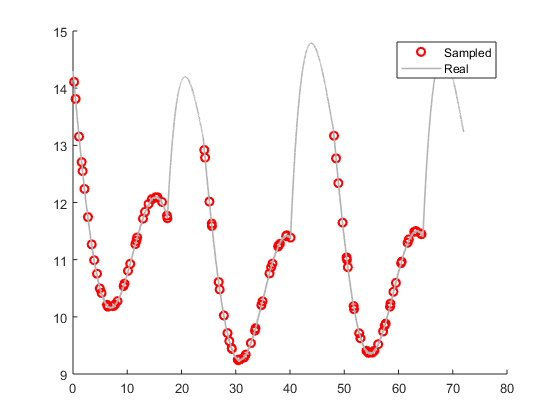

figure(1); 
scatter(cell2mat(dtd.t(1:3)),cell2mat(dtd.y(1:3)),'r','LineWidth',1.6); hold on;
for i = 1 : 3
    plot(dta.td{i},dta.yd{i},'Color',[.7 .7 .7],'LineWidth',1.2); hold on;
    if i ~= length(dta.yo)
        plot(dta.tn{i},dta.yn{i},'Color',[.7 .7 .7],'LineWidth',1.2);
    end
end
legend([{'Sampled'},{'Real'}])
hold off;

## Determine the estimation and validation data

est_d = 7;

dte.y = dtd.y(1:est_d); dte.t = dtd.t(1:est_d);
dte.init = dtd.initial(1:est_d); dte.final = dtd.final(1:est_d); 
dte.valid.y = dtd.y(est_d+1:end); dte.valid.t = dtd.t(est_d+1:end);
dte.valid.init = dtd.initial(est_d+1:end); dte.valid.final = dtd.final(est_d+1:end);

## Select the model structure

It is possible to select the filtereing structure by a *trivial* form ***i.e.*** setting the filtering poles $\omega_c = \frac{\pi}{2}$ or by using a derivative-free *barycenter *approach for searching the best choice 

struc = struc_select('trivial',dte);

## Estimate the models parameters

parameters = est_regr(dte,struc,'16','ls');

## Simulate the alertness level

time.init = [dte.valid.t{1}(1), dte.valid.init(2:end)];
time.final = dte.valid.final;
initial = dte.valid.y{1}(1);

dts = sim_system(parameters,time,initial);

## Figures Generation

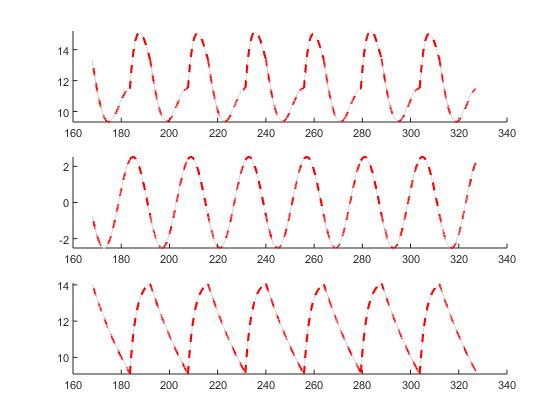

figure(4); 
for i = 1 : length(dts.y)
    i_s = i + est_d;
    subplot(3,1,1); hold on;
    plot(dta.td{i_s},dta.yo{i_s},'Color',[.8 .8 .8]); hold on;
    plot(dts.td{i},dts.yd{i},'r--','LineWidth',1.6);
    subplot(3,1,2); hold on;
    plot(dta.td{i_s},dta.yo{i_s} - dta.dhom{i_s},'Color',[.8 .8 .8]); hold on;
    plot(dts.td{i},dts.yd{i} - dts.dhom{i},'r--','LineWidth',1.6);
    subplot(3,1,3); hold on;
    plot(dta.td{i_s},dta.dhom{i_s},'Color',[.8 .8 .8]); hold on;
    plot(dts.td{i},dts.dhom{i},'r--','LineWidth',1.6);
   
    if i ~= length(dts.y)
        subplot(3,1,1); hold on;
        plot(dta.tn{i_s},dta.yn{i_s},'Color',[.8 .8 .8]); hold on;
        plot(dts.tn{i},dts.yn{i},'r--','LineWidth',1.6);
        subplot(3,1,2); hold on;
        plot(dta.tn{i_s},dta.yn{i_s} - dta.nhom{i_s},'Color',[.8 .8 .8]); hold on;
        plot(dts.tn{i},dts.yn{i} - dts.nhom{i},'r--','LineWidth',1.6);
        subplot(3,1,3); hold on;
        plot(dta.tn{i_s},dta.nhom{i_s},'Color',[.8 .8 .8]); hold on;
        plot(dts.tn{i},dts.nhom{i},'r--','LineWidth',1.6);    
    end
end